# MATLAB大作业（COVID-19疫情数据的简要统计分析与预测）

王逸扬（19300180016）、杨耕智（19300180112）

项目的完整内容请参见[`https://github.com/maix00/StatisticsAnalysis`](https://github.com/maix00/StatisticsAnalysis).

clear; clc;
format long
path_country = './data/COVID19/country.csv';
path_daily = './data/COVID19/daily_info.csv';
country_SA = StatisticsAnalysis('TablePath', path_country);
country = country_SA.Table;
daily_SA = StatisticsAnalysis('TablePath', path_daily, ...
    'ImportOptions', {'VariableTypes', {'new_vaccinations', 'double', 'total_vaccinations', 'double'}} ...
    );
daily = daily_SA.Table;

% 得到每日数据中的无缺国家特征数据
daily_location = unique(daily{:,'location'});
country_location = unique(country{:,'location'});
country_daily = country(ismember(country_location, daily_location), :);
country_daily(any(ismissing(country_daily)')',:) = [];
% 得到国家数据中的无缺国家特征数据
country_nomissing = country;
country_nomissing(any(ismissing(country)')',:) = [];

% Asia, Oceania, Europe, Africa, North America, South America
country_Asia = country_SA.Update('SelectTableOptions', {'continent', 'Asia'}).Table;
country_mean_Asia = country_Asia(1, 2:end);
for vn_idx = country_mean_Asia.Properties.VariableNames(2:end)
    vn = vn_idx{1};
    country_mean_Asia{1,vn} = tsnanmean(country_Asia.(vn));
end
country_Oceania = country_SA.Update('SelectTableOptions', {'continent', 'Oceania'}).Table;
country_mean_Oceania = country_Oceania(1, 2:end);
for vn_idx = country_mean_Oceania.Properties.VariableNames(2:end)
    vn = vn_idx{1};
    country_mean_Oceania{1,vn} = tsnanmean(country_Oceania.(vn));
end
country_Europe = country_SA.Update('SelectTableOptions', {'continent', 'Europe'}).Table;
country_mean_Europe = country_Europe(1, 2:end);
for vn_idx = country_mean_Europe.Properties.VariableNames(2:end)
    vn = vn_idx{1};
    country_mean_Europe{1,vn} = tsnanmean(country_Europe.(vn));
end
country_Africa = country_SA.Update('SelectTableOptions', {'continent', 'Africa'}).Table;
country_mean_Africa = country_Africa(1, 2:end);
for vn_idx = country_mean_Africa.Properties.VariableNames(2:end)
    vn = vn_idx{1};
    country_mean_Africa{1,vn} = tsnanmean(country_Africa.(vn));
end
country_North_America = country_SA.Update('SelectTableOptions', {'continent', 'North America'}).Table;
country_mean_North_America = country_North_America(1, 2:end);
for vn_idx = country_mean_North_America.Properties.VariableNames(2:end)
    vn = vn_idx{1};
    country_mean_North_America{1,vn} = tsnanmean(country_North_America.(vn));
end
country_South_America = country_SA.Update('SelectTableOptions', {'continent', 'South America'}).Table;
country_mean_South_America = country_South_America(1, 2:end);
for vn_idx = country_mean_South_America.Properties.VariableNames(2:end)
    vn = vn_idx{1};
    country_mean_South_America{1,vn} = tsnanmean(country_South_America.(vn));
end
country_tackled = country;
for idx = 1: size(country_tackled, 1)
    for idxx = 3: size(country_tackled, 2)
        if ismissing(country{idx, idxx})
            switch country{idx, 'continent'}{1}
                case 'Asia', country_this_mean = country_mean_Asia;
                case 'Oceania', country_this_mean = country_mean_Oceania;
                case 'Europe', country_this_mean = country_mean_Europe;
                case 'Africa', country_this_mean = country_mean_Africa;
                case 'North America', country_this_mean = country_mean_North_America;
                case 'South America', country_this_mean = country_mean_South_America;
            end
            country_tackled(idx, idxx) = country_this_mean(1, idxx-1);
        end
    end
end

### Chapter 5: 短期性分析第一种路径（基于LSTM模型的分析预测）

#### 5.1 聚类分析

% 对全部128个无缺国家的聚类分析
% C = country_nomissing;
C = country_tackled;
% 数据准备
C = removevars(C, {'continent', 'population'});%, 'gdp_per_capita'});
C = addvars(C, (C.male_smokers+C.female_smokers)/2, 'NewVariableNames', 'smokers');
C = removevars(C, {'male_smokers', 'female_smokers'});
data = table2array(removevars(C,'location'));
% 主成分分析
[coeff, score, latent] = pca(data);
ratio = latent/sum(latent);
data_cut = score(:,1:5);

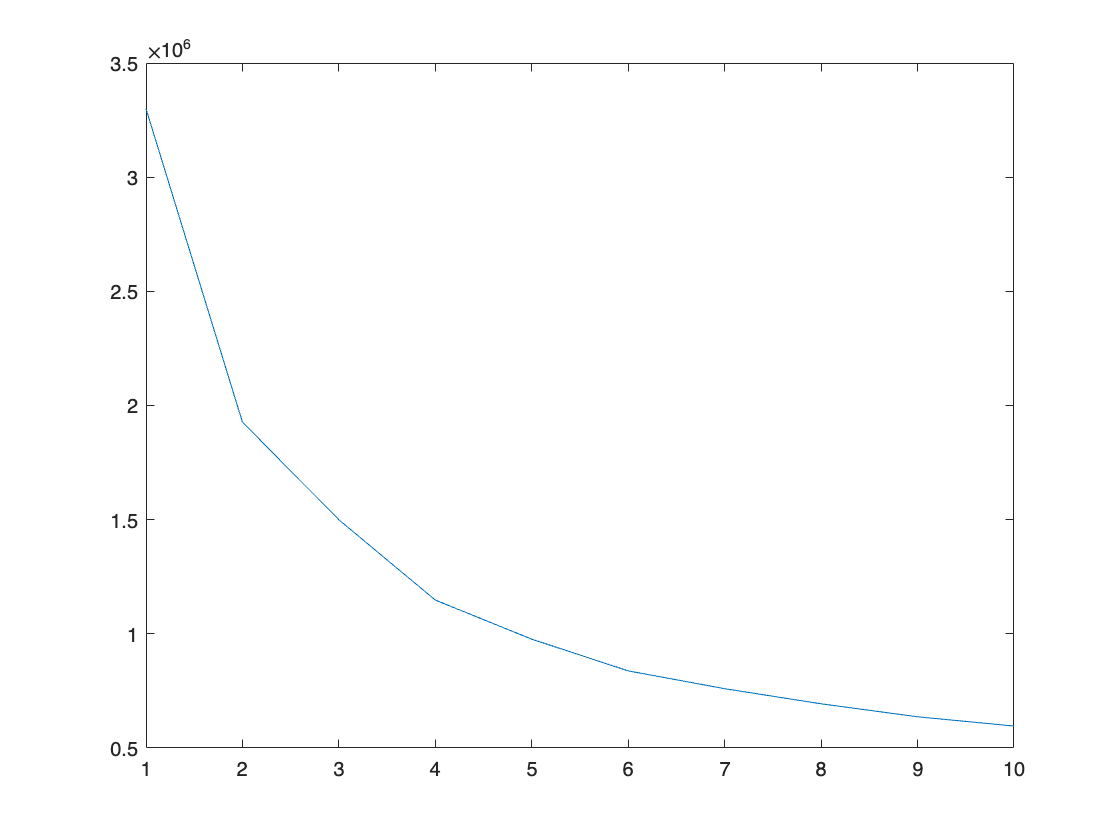

% 肘部法则
elbow_2(data_cut, C.location, 10);

% dbscan
% idxx = dbscan(data_cut, 65, 2);
% k-mean
country_types = Divide_types_2(data_cut, C.location, 4);
% 显示分类
for ii = 1: size(country_types,1), country_types{ii,2} = length(country_types{ii,1}); end
[~, index] = sort(cell2mat(country_types(:,2)));
country_types = country_types(index, 1);
for ii = 1: size(country_types,1), display(country_types{ii,1}); end

  1×9 cell array
  Columns 1 through 8
    {'Brunei'}    {'Ireland'}    {'Kuwait'}    {'Luxembourg'}    {'Macao'}    {'Norway'}    {'Qatar'}    {'Singapore'}
  Column 9
    {'United Arab Emirates'}
  1×44 cell array
  Columns 1 through 8
    {'Andorra'}    {'Aruba'}    {'Australia'}    {'Austria'}    {'Bahrain'}    {'Belgium'}    {'Bermuda'}    {'Canada'}
  Columns 9 through 16
    {'Cayman Islands'}    {'Cyprus'}    {'Czechia'}    {'Denmark'}    {'Faeroe Islands'}    {'Finland'}    {'France'}    {'Germany'}
  Columns 17 through 24
    {'Gibraltar'}    {'Guernsey'}    {'Hong Kong'}    {'Iceland'}    {'Isle of Man'}    {'Israel'}    {'Italy'}    {'Japan'}
  Columns 25 through 32
    {'Jersey'}    {'Liechtenstein'}    {'Malta'}    {'Monaco'}    {'Netherlands'}    {'New Zealand'}    {'Oman'}    {'Puerto Rico'}
  Columns 33 through 39
    {'San Marino'}    {'Saudi Arabi

% 以上结果在地理图上的可视化
countries = shaperead('./world_countries/World_countries.shp', 'UseGeoCoords', true);
tp = readtable('./countries_name.txt');
tp2 = readtable('./countries_name_2.txt');
for idx = 1: length(country_location)
    if ~any(strcmp(country_location{idx}, tp.location)) && ~any(strcmp(country_location{idx}, tp2.location))
        display(country_location{idx});
    end
end

Bonaire Sint Eustatius and Saba
Curacao
Guam
Guernsey
Hong Kong
Isle of Man
Jersey
Kosovo
Macao
Northern Cyprus
Palestine
Sint Maarten (Dutch part)
Taiwan


country_types_2 = cell(length(country_types),1);
for idx = 1: length(country_types), country_types_2{idx} = struct.empty; end
for idx = 1: length(country_types)
    for idxx = 1: length(country_types{idx})
        map1 = strcmp(country_types{idx}{idxx}, tp.location);
        map2 = strcmp(country_types{idx}{idxx}, tp2.location);
        if any(map1)
            map1 = ismember({countries.FENAME}, tp.FENAME(map1,:));
            country_types_2{idx} = [country_types_2{idx}; countries(map1)];
        elseif any(map2)
            map2 = ismember({countries.NAME}, tp2.NAME(map2,:));
            country_types_2{idx} = [country_types_2{idx}; countries(map2)];
        end
    end
end

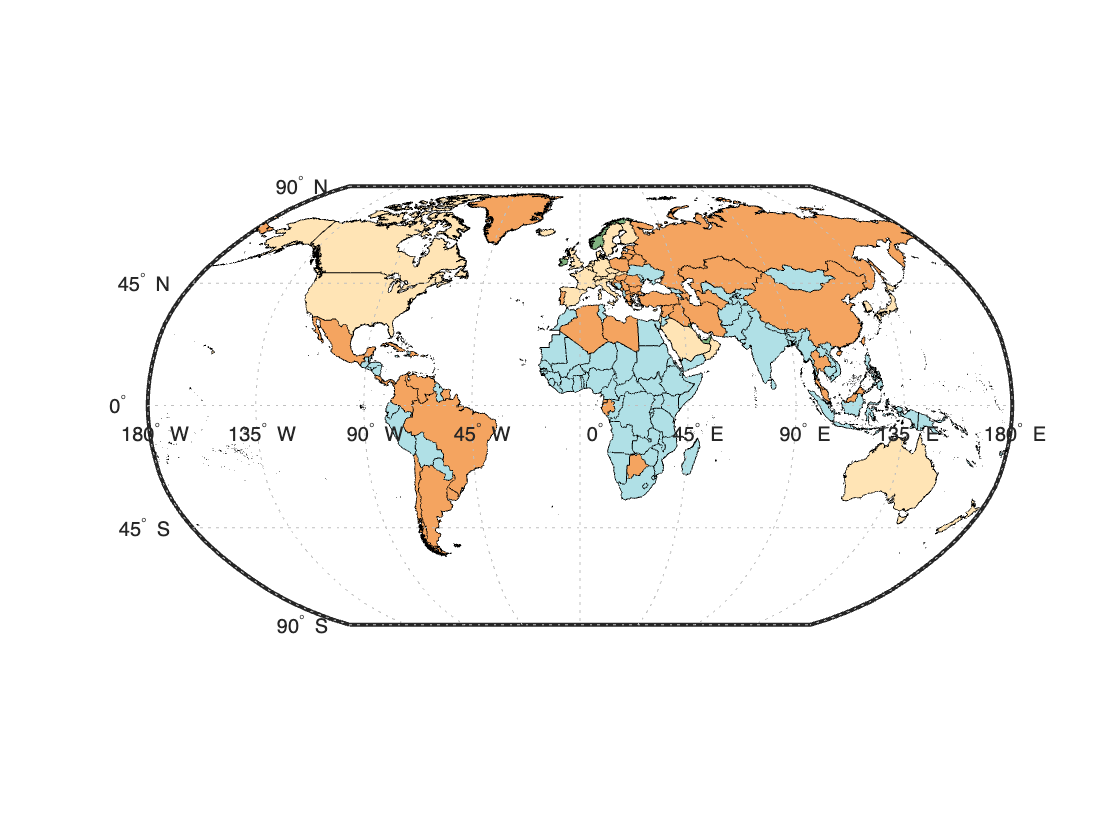

ax = worldmap('World');
geoshow(ax, country_types_2{1}, 'FaceColor', [0.5 0.7 0.5]);
geoshow(ax, country_types_2{2}, 'FaceColor', [255 228 181]/255);
geoshow(ax, country_types_2{3}, 'FaceColor', [244 164 96]/255);
geoshow(ax, country_types_2{4}, 'FaceColor', [176 224 230]/255);

% 其中对20个国家的聚类分析
CT = country_types;
for idx = 1: size(CT, 1)
    CT{idx} = CT{idx}(ismember(CT{idx}, country_daily.location));
    display(CT{idx,1});
end

  1×1 cell array
    {'Ireland'}
  1×10 cell array
  Columns 1 through 8
    {'Australia'}    {'Canada'}    {'France'}    {'Germany'}    {'Iceland'}    {'Japan'}    {'Saudi Arabia'}    {'South Korea'}
  Columns 9 through 10
    {'Sweden'}    {'United States'}
  1×5 cell array
    {'Chile'}    {'China'}    {'Hungary'}    {'Malaysia'}    {'Thailand'}
  1×4 cell array
    {'Egypt'}    {'Ethiopia'}    {'South Africa'}    {'Zimbabwe'}


#### 5.1 构建模型

country_names = {'China','France','Ethiopia','Zimbabwe','Hungary','South Korea','Egypt','Australia','Canada','Iceland'};
[XSeq_train, YSeq_train, XSeq_test, YSeq_test, muY, sigY] = Data_Preparation(country_names,true);

Training:

net = PredictNet(XSeq_train,YSeq_train);

#### 5.3 预测分析

Testing on following dates:

NUM = 2;
Xtest = XSeq_test{NUM,1};
Ytest = YSeq_test{NUM,1};
net = resetState(net);
net = predictAndUpdateState(net,XSeq_train{NUM,1});
numTimeStepsTest = size(Xtest,2);
YPred = zeros(1,numTimeStepsTest);
for i = 1:numTimeStepsTest
    [net,YPred(1,i)] = predictAndUpdateState(net,Xtest(:,i),'ExecutionEnvironment','gpu');
end
relerr = norm(YPred-Ytest)/norm(Ytest);
disp(relerr)
clf;
YPred = (YPred * sigY{1,NUM}) + muY{1,NUM};
Ytest = (Ytest * sigY{1,NUM}) + muY{1,NUM};
% previous
Yprevious = (YSeq_train{NUM,1}*sigY{1,NUM}) + muY{1,NUM};

plot(1:size(Yprevious,2),Yprevious);
hold on;
plot(size(YSeq_train{NUM,1},2)+1:size(YSeq_train{NUM,1},2)+size(YPred,2),YPred);
plot(size(YSeq_train{NUM,1},2)+1:size(YSeq_train{NUM,1},2)+size(YPred,2),Ytest);
legend('Previous','Pred','Real')
title(country_names{1,NUM});